检查 has_non_reuse 和最终的 different registers 是否线性相关

% 数据定义
model1_nonreuse = [186, 228, 204, 220, 227, 222, 212, 216, 208, 223, 201, 223, 235, 211, 225, 215, 239, 186, 251, 239];
model2_nonreuse = [260, 234, 218, 201, 239, 199, 229, 205, 200, 199, 232, 186, 213, 245, 222, 202, 234, 206, 209, 213];
different_regs = [451, 591, 482, 473, 542, 444, 489, 670, 451, 468, 472, 432, 452, 427, 467, 449, 420, 459, 443, 447];

% 确保数据为列向量
model1_nonreuse = model1_nonreuse(:);
model2_nonreuse = model2_nonreuse(:);
different_regs = different_regs(:);

fprintf('=== 线性相关性分析 ===\n\n');

=== 线性相关性分析 ===




%% 1. 直接相关性分析
fprintf('1. 直接相关性分析:\n');

1. 直接相关性分析:


fprintf('----------------------------------------\n');

----------------------------------------



% model1_nonreuse 与 different_regs 的相关性
[r1, p1] = corr(model1_nonreuse, different_regs);
fprintf('model1_nonreuse 与 different_regs:\n');

model1_nonreuse 与 different_regs:


fprintf('相关系数 r = %.4f, p值 = %.4f\n', r1, p1);

相关系数 r = -0.0243, p值 = 0.9189



% model2_nonreuse 与 different_regs 的相关性
[r2, p2] = corr(model2_nonreuse, different_regs);
fprintf('model2_nonreuse 与 different_regs:\n');

model2_nonreuse 与 different_regs:


fprintf('相关系数 r = %.4f, p值 = %.4f\n\n', r2, p2);

相关系数 r = 0.0627, p值 = 0.7929




%% 2. 数字组合与 different_regs 的相关性
fprintf('2. 数字组合与 different_regs 的相关性:\n');

2. 数字组合与 different_regs 的相关性:


fprintf('----------------------------------------\n');

----------------------------------------



% 定义各种组合
combinations = {
    model1_nonreuse + model2_nonreuse, '相加 (model1 + model2)';
    model1_nonreuse - model2_nonreuse, '相减 (model1 - model2)';
    model2_nonreuse - model1_nonreuse, '相减 (model2 - model1)';
    (model1_nonreuse + model2_nonreuse)/2, '平均值';
    model1_nonreuse .* model2_nonreuse, '相乘';
    model1_nonreuse ./ model2_nonreuse, '相除 (model1/model2)';
    abs(model1_nonreuse - model2_nonreuse), '绝对差值';
    sqrt(model1_nonreuse.^2 + model2_nonreuse.^2), '平方和开根';
};

% 计算每种组合与 different_regs 的相关性
results = [];
for i = 1:size(combinations, 1)
    combination_data = combinations{i, 1};
    combination_name = combinations{i, 2};
    
    [r, p] = corr(combination_data, different_regs);
    
    fprintf('%s:\n', combination_name);
    fprintf('  相关系数 r = %.4f, p值 = %.4f\n', r, p);
    
    % 存储结果
    results(i).name = combination_name;
    results(i).r = r;
    results(i).p = p;
end

相加 (model1 + model2):


  相关系数 r = 0.0351, p值 = 0.8832


相减 (model1 - model2):


  相关系数 r = -0.0572, p值 = 0.8108


相减 (model2 - model1):


  相关系数 r = 0.0572, p值 = 0.8108


平均值:


  相关系数 r = 0.0351, p值 = 0.8832


相乘:


  相关系数 r = 0.0486, p值 = 0.8387


相除 (model1/model2):


  相关系数 r = -0.0826, p值 = 0.7291


绝对差值:


  相关系数 r = -0.3420, p值 = 0.1400


平方和开根:


  相关系数 r = 0.0195, p值 = 0.9350



%% 3. 显著性检验和结果排序
fprintf('\n3. 相关性强度排序 (按绝对值):\n');


3. 相关性强度排序 (按绝对值):


fprintf('----------------------------------------\n');

----------------------------------------



% 按相关系数绝对值排序
[~, sorted_idx] = sort(abs([results.r]), 'descend');

for i = 1:length(sorted_idx)
    idx = sorted_idx(i);
    significance = '';
    if results(idx).p < 0.05
        significance = '** 显著 **';
    elseif results(idx).p < 0.1
        significance = '* 边缘显著 *';
    end
    
    fprintf('%2d. %s: r = %7.4f, p = %6.4f %s\n', ...
        i, results(idx).name, results(idx).r, results(idx).p, significance);
end

 1. 绝对差值: r = -0.3420, p = 0.1400 
 2. 相除 (model1/model2): r = -0.0826, p = 0.7291 
 3. 相减 (model1 - model2): r = -0.0572, p = 0.8108 
 4. 相减 (model2 - model1): r =  0.0572, p = 0.8108 
 5. 相乘: r =  0.0486, p = 0.8387 
 6. 相加 (model1 + model2): r =  0.0351, p = 0.8832 
 7. 平均值: r =  0.0351, p = 0.8832 
 8. 平方和开根: r =  0.0195, p = 0.9350 


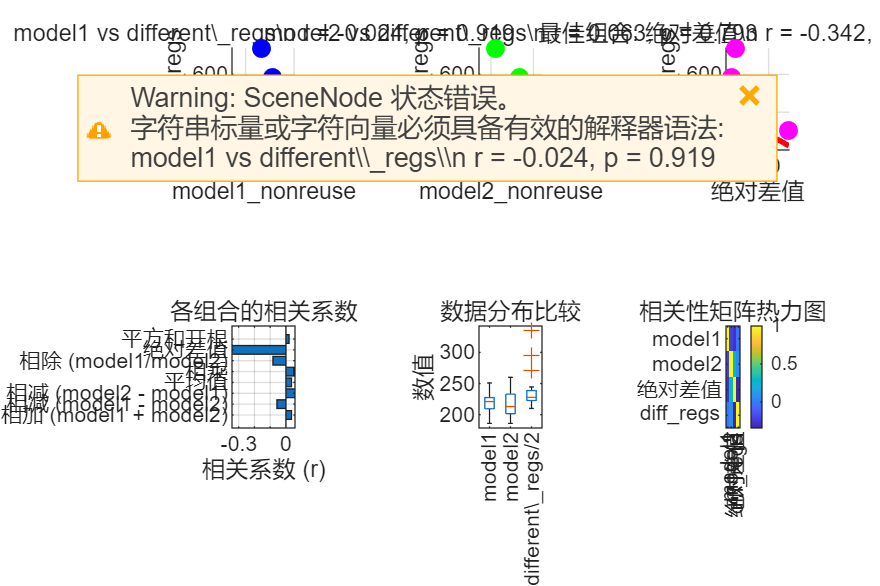


%% 4. 可视化分析
figure('Position', [100, 100, 1200, 800]);

% 子图1: 直接相关性散点图
subplot(2, 3, 1);
scatter(model1_nonreuse, different_regs, 50, 'filled', 'b');
hold on;
p = polyfit(model1_nonreuse, different_regs, 1);
yfit = polyval(p, model1_nonreuse);
plot(model1_nonreuse, yfit, 'r-', 'LineWidth', 2);
xlabel('model1\_nonreuse');
ylabel('different\_regs');
title(sprintf('model1 vs different\\_regs\\n r = %.3f, p = %.3f', r1, p1));
grid on;

subplot(2, 3, 2);
scatter(model2_nonreuse, different_regs, 50, 'filled', 'g');
hold on;
p = polyfit(model2_nonreuse, different_regs, 1);
yfit = polyval(p, model2_nonreuse);
plot(model2_nonreuse, yfit, 'r-', 'LineWidth', 2);
xlabel('model2\_nonreuse');
ylabel('different\_regs');
title(sprintf('model2 vs different\\_regs\\n r = %.3f, p = %.3f', r2, p2));
grid on;

% 子图3: 最佳组合的相关性
best_idx = sorted_idx(1);
best_combination = combinations{best_idx, 1};
best_name = combinations{best_idx, 2};

subplot(2, 3, 3);
scatter(best_combination, different_regs, 50, 'filled', 'm');
hold on;
p = polyfit(best_combination, different_regs, 1);
yfit = polyval(p, best_combination);
plot(best_combination, yfit, 'r-', 'LineWidth', 2);
xlabel(best_name);
ylabel('different\_regs');
title(sprintf('最佳组合: %s\\n r = %.3f, p = %.3f', best_name, results(best_idx).r, results(best_idx).p));
grid on;

% 子图4: 相关系数条形图
subplot(2, 3, 4);
r_values = [results.r];
barh(r_values);
set(gca, 'YTickLabel', {results.name});
xlabel('相关系数 (r)');
title('各组合的相关系数');
grid on;

% 子图5: 数据分布
subplot(2, 3, 5);
boxplot([model1_nonreuse, model2_nonreuse, different_regs/2], ...
    'Labels', {'model1', 'model2', 'different\_regs/2'});
ylabel('数值');
title('数据分布比较');

% 子图6: 热力图显示相关性矩阵
subplot(2, 3, 6);
correlation_matrix = corr([model1_nonreuse, model2_nonreuse, ...
    best_combination, different_regs]);
imagesc(correlation_matrix);
colorbar;
set(gca, 'XTick', 1:4, 'XTickLabel', {'model1', 'model2', best_name, 'diff\_regs'});
set(gca, 'YTick', 1:4, 'YTickLabel', {'model1', 'model2', best_name, 'diff\_regs'});
title('相关性矩阵热力图');


%% 5. 线性回归分析
fprintf('\n4. 线性回归分析 (最佳组合):\n');


4. 线性回归分析 (最佳组合):


fprintf('----------------------------------------\n');

----------------------------------------



X = [ones(size(best_combination)), best_combination]; % 添加常数项
[b, bint, r, rint, stats] = regress(different_regs, X);

fprintf('回归方程: different_regs = %.2f + %.2f * %s\n', b(1), b(2), best_name);

回归方程: different_regs = 504.21 + -1.26 * 绝对差值


fprintf('R² = %.4f, F统计量 = %.4f, p值 = %.4f\n', stats(1), stats(2), stats(3));

R² = 0.1169, F统计量 = 2.3837, p值 = 0.1400


fprintf('系数95%%置信区间: [%.4f, %.4f]\n', bint(2,1), bint(2,2));

系数95%置信区间: [-2.9720, 0.4542]



%% 6. 输出总结
fprintf('\n5. 分析总结:\n');


5. 分析总结:


fprintf('----------------------------------------\n');

----------------------------------------


fprintf('样本数量: %d\n', length(model1_nonreuse));

样本数量: 20


fprintf('model1_nonreuse 均值: %.2f ± %.2f\n', mean(model1_nonreuse), std(model1_nonreuse));

model1_nonreuse 均值: 218.55 ± 16.68


fprintf('model2_nonreuse 均值: %.2f ± %.2f\n', mean(model2_nonreuse), std(model2_nonreuse));

model2_nonreuse 均值: 217.30 ± 18.96


fprintf('different_regs 均值: %.2f ± %.2f\n', mean(different_regs), std(different_regs));

different_regs 均值: 476.45 ± 60.20



% 判断相关性强度
best_r = results(best_idx).r;
if abs(best_r) >= 0.7
    strength = '强';
elseif abs(best_r) >= 0.5
    strength = '中等';
elseif abs(best_r) >= 0.3
    strength = '弱';
else
    strength = '很弱';
end

fprintf('\n最佳相关性: %s (%s相关性)\n', best_name, strength);


最佳相关性: 绝对差值 (弱相关性)


2025.10.11 test 检测算法 100 轮迭代效果

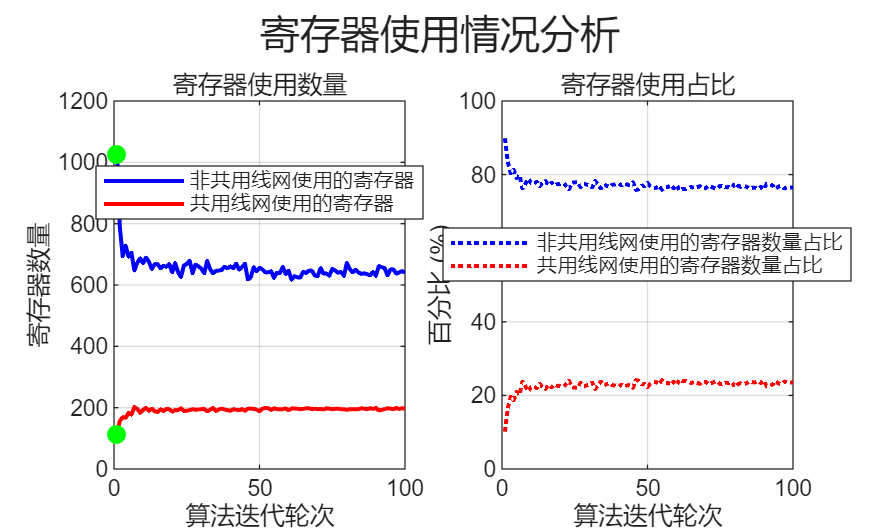

cycle = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15, 16, 17, 18, 19, 20, 21, 22, 23, 24, 25, 26, 27, 28, 29, 30, 31, 32, 33, 34, 35, 36, 37, 38, 39, 40, 41, 42, 43, 44, 45, 46, 47, 48, 49, 50, 51, 52, 53, 54, 55, 56, 57, 58, 59, 60, 61, 62, 63, 64, 65, 66, 67, 68, 69, 70, 71, 72, 73, 74, 75, 76, 77, 78, 79, 80, 81, 82, 83, 84, 85, 86, 87, 88, 89, 90, 91, 92, 93, 94, 95, 96, 97, 98, 99, 100];
has_non_reuse = [1046, 789, 693, 729, 692, 705, 647, 673, 687, 671, 690, 676, 652, 668, 668, 654, 663, 659, 668, 641, 672, 642, 626, 663, 669, 679, 638, 667, 661, 653, 638, 679, 652, 638, 646, 647, 649, 660, 654, 661, 655, 670, 650, 658, 670, 618, 625, 658, 645, 656, 651, 641, 641, 645, 623, 641, 638, 659, 636, 647, 617, 629, 625, 624, 643, 639, 647, 647, 631, 629, 655, 637, 638, 630, 653, 647, 640, 643, 630, 672, 652, 641, 650, 641, 636, 638, 635, 631, 643, 630, 662, 658, 655, 631, 651, 651, 637, 641, 645, 641];
only_reuse = [118, 157, 169, 167, 183, 177, 202, 196, 183, 193, 199, 190, 197, 188, 186, 195, 189, 196, 195, 187, 192, 192, 198, 189, 190, 192, 195, 193, 194, 195, 196, 188, 193, 199, 189, 194, 197, 194, 192, 190, 195, 194, 191, 195, 190, 197, 197, 196, 194, 188, 197, 199, 198, 193, 198, 195, 195, 195, 198, 191, 198, 197, 197, 195, 196, 198, 198, 195, 197, 195, 196, 194, 198, 197, 195, 196, 197, 195, 195, 193, 195, 195, 195, 195, 198, 197, 195, 198, 196, 199, 191, 193, 195, 198, 197, 195, 199, 196, 198, 197];
TOTAL_AVG_LENGTH = [2919, 2883, 2886, 2885, 2885, 2887, 2884, 2885, 2886, 2885, 2888, 2887, 2886, 2887, 2887, 2887, 2888, 2887, 2886, 2887, 2887, 2889, 2886, 2889, 2888, 2888, 2889, 2888, 2886, 2887, 2888, 2888, 2886, 2888, 2887, 2887, 2888, 2887, 2887, 2887, 2887, 2886, 2887, 2888, 2887, 2888, 2887, 2887, 2887, 2887, 2887, 2887, 2886, 2890, 2886, 2888, 2887, 2888, 2887, 2887, 2889, 2886, 2887, 2888, 2887, 2888, 2887, 2889, 2887, 2888, 2887, 2888, 2887, 2887, 2888, 2887, 2888, 2887, 2887, 2888, 2887, 2887, 2888, 2887, 2888, 2887, 2888, 2887, 2887, 2889, 2888, 2887, 2887, 2888, 2890, 2888, 2887, 2888, 2887, 2887];

total_use = has_non_reuse + only_reuse;
has_non_reuse_ratio = has_non_reuse ./ total_use * 100;
only_reuse_ratio = only_reuse ./ total_use * 100;

basiccost_has_non_reuse = 1026;
basiccost_only_reuse = 111;
basiccost_TOTAL_LENGTH = 2910;

best_TOTAL_LENGTH = 2880;

% 创建子图
figure;

% 左子图 - 显示寄存器数量
subplot(1,2,1);
plot(cycle, has_non_reuse, 'b-', 'LineWidth', 1.5);
hold on;
plot(cycle, only_reuse, 'r-', 'LineWidth', 1.5);
scatter(1, basiccost_has_non_reuse, 50, 'g', 'fill');
scatter(1, basiccost_only_reuse, 50, 'g', 'fill');
ylabel('寄存器数量');
xlabel('算法迭代轮次');
legend({'非共用线网使用的寄存器','共用线网使用的寄存器'}, 'Location','best');
title('寄存器使用数量');
grid on;

% 右子图 - 显示百分比
subplot(1,2,2);
plot(cycle, has_non_reuse_ratio, 'b:', 'LineWidth', 1.5);
hold on;
plot(cycle, only_reuse_ratio, 'r:', 'LineWidth', 1.5);
ylabel('百分比 (%)');
xlabel('算法迭代轮次');
legend({'非共用线网使用的寄存器数量占比','共用线网使用的寄存器数量占比'}, 'Location','best');
title('寄存器使用占比');
grid on;

% 调整整体标题（可选）
sgtitle('寄存器使用情况分析');

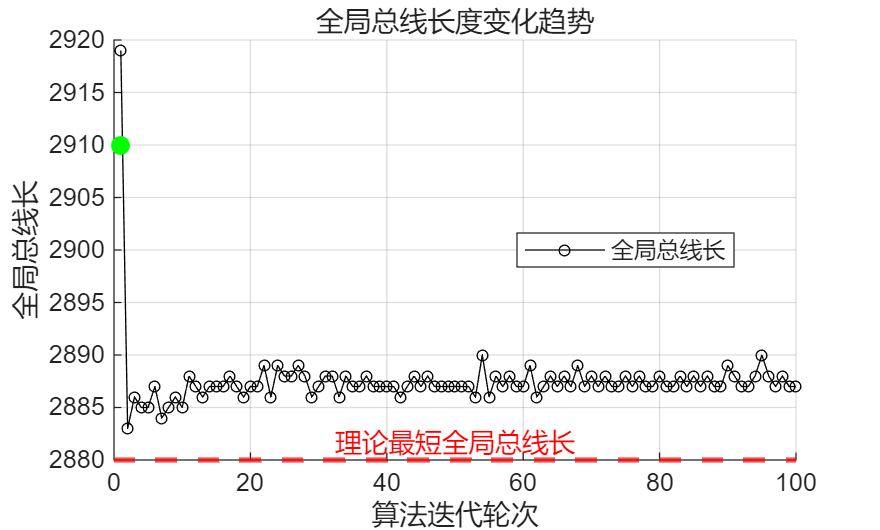


% 总线长度趋势图
figure;
hold on;
plot(cycle, TOTAL_AVG_LENGTH, 'k-o', 'MarkerSize',4);
scatter(1, basiccost_TOTAL_LENGTH, 50, 'g', 'fill');
xlabel('算法迭代轮次');
ylabel('全局总线长');
yline(best_TOTAL_LENGTH, 'r--', 'LineWidth', 2, 'Label', '理论最短全局总线长', 'LabelHorizontalAlignment', 'center');
legend('全局总线长', 'Location','best');
title('全局总线长度变化趋势');
grid on;

2025.10.11 test 检测平均修改寄存器数

cycle = [1, 2, 3, 4, 5, 6, 7, 8, 9, 10, 11, 12, 13, 14, 15]

cycle =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15


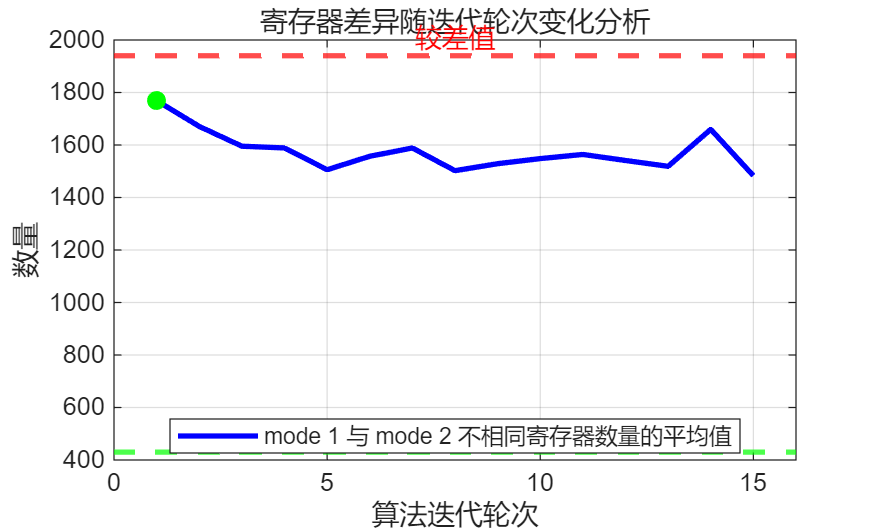

avg_diff_reg = [1769.2, 1670.8, 1595.4, 1588.8, 1505.8, 1557.0, 1588.6, 1502.2, 1528.8, 1548.2, 1564.0, 1541.0, 1518.8, 1659.6, 1483];
ideal_diff_reg = 430;
bad_diff_reg = 1940;
basiccost_diff_reg = 1767.8;

% 创建图形
figure;
plot(cycle, avg_diff_reg, 'b-', 'LineWidth', 2, 'MarkerSize', 6, 'MarkerFaceColor', 'b');
hold on;

% 在cycle=1的位置标出basiccost_diff_reg
scatter(1, basiccost_diff_reg, 50, 'g', 'filled');

% 用水平线标出ideal_diff_reg和bad_diff_reg
yline(ideal_diff_reg, 'g--', 'LineWidth', 2, 'Label', '理想值', 'LabelHorizontalAlignment', 'center');
yline(bad_diff_reg, 'r--', 'LineWidth', 2, 'Label', '较差值', 'LabelHorizontalAlignment', 'center');

% 设置图形属性
xlabel('算法迭代轮次');
ylabel('数量');
title('寄存器差异随迭代轮次变化分析');
legend('mode 1 与 mode 2 不相同寄存器数量的平均值', 'Location', 'best');
grid on;

% 设置坐标轴范围，确保所有数据点都可见
xlim([0, 16]);
ylim([400, 2000]);